clear all
close all
clc
warning off

% Set paths
addpath input\
addpath subroutines\

% Load variables (Shock series, outcome variables, definition time period
load("input/settings.mat")
load("input/shocks.mat")
load("input/production.mat")
load("input/temperature.mat")

%%% IP Estimation and Plotting: Federal level

%% Configuration
% Define length of the predicted horizon
H=0:12;

% Define the number of time series for which the IRF shall be computed
n_spec=5;

% Define period of available time series
ind1 = find(strcmp('01-Jan-1991',cMonths));
ind2 = find(strcmp('01-Dec-2019',cMonths));
data=nan(ind2-ind1+1,n_spec);

% Read all data for which IRF shall be computed
data(:,1)=production{1,1}.ip_bcdf(ind1:ind2);
data(:,2)=production{1,1}.ip_energy_intensive(ind1:ind2);
data(:,3)=production{1,1}.ip_b(ind1:ind2);
data(:,4)=production{1,1}.ip_c(ind1:ind2);
data(:,5)=production{1,1}.ip_d(ind1:ind2);

% Estimating log-model
data = log(data);

% Read shock series
shock = shocks{1,1}.estimates(ind1:ind2, 1);
scaler = 100*sqrt(var(shock,'omitnan'));

% Testing for unit root (Optional)
for i=1:n_spec
    % Using a pre-defined sub-routine here
    adf_obj = adf_ic(data(:,i),'AIC',0,13,'ARD');
    ColNames = {'TestStatistic', 'pValue', 'LagOrder_FD', 'IC', 'Deterministics'};
    ADF_Table_FF = table(adf_obj.stat,adf_obj.pValue,...
    adf_obj.lag,adf_obj.ICs,adf_obj.deters, 'VariableNames',ColNames)
end

ADF_Table_FF = 1×5 table
    TestStatistic    pValue     LagOrder_FD      IC       Deterministics
    _____________    _______    ___________    _______    ______________

       -1.1615       0.66702         5         {'AIC'}     {'constant'} 


ADF_Table_FF = 1×5 table
    TestStatistic    pValue     LagOrder_FD      IC       Deterministics
    _____________    _______    ___________    _______    ______________

       -1.1543       0.66369         0         {'AIC'}     {'constant'} 


ADF_Table_FF = 1×5 table
    TestStatistic    pValue     LagOrder_FD      IC       Deterministics
    _____________    _______    ___________    _______    ______________

      -0.057702      0.95146         5         {'AIC'}     {'constant'} 


ADF_Table_FF = 1×5 table
    TestStatistic    pValue    LagOrder_FD      IC       Deterministics
    _____________    ______    ___________    _______    ______________

       -1.1273       0.6821         5         {'AIC'}     {'constant'} 


ADF_Table_FF = 1×5 table
    TestStatistic     pValue     LagOrder_FD      IC       Deterministics
    _____________    ________    ___________    _______    ______________

       -2.9705       0.038872         4         {'AIC'}     {'constant'} 


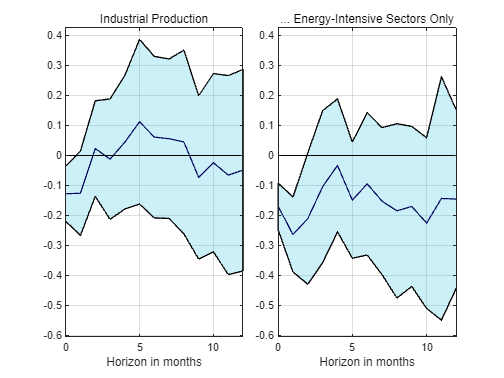


%% Estimation
% Initialize IRF and SE matrices
irf=nan(size(H,2),n_spec);
se=nan(size(H,2),n_spec);

% Compute impulse response for every horizon
for n=1:n_spec
    for i=0:size(H,2)-1
        s_selec=lagmatrix(shock,i);
        y=data(:,n)-lagmatrix(data(:,n),i+1);  
        X=[s_selec,lagmatrix(data(:,n),i+1)-lagmatrix(data(:,n),i+2)]; 
        
        if i==0
        [~,se_est,beta]=hac(X,y,Type='HC',Intercept=true,Display="off");
        else
        [~,se_est,beta]=hac(X,y,Type='HAC',Bandwidth=i,Intercept=true,Display="off");
        end

        % Store results
        irf(i+1,n)=beta(2);
        se(i+1,n)=se_est(2);
    end
end


%% Plot IRF
cVarname={'Industrial Production', '... Energy-Intensive Sectors Only'};

f1=tiledlayout(1,2,"TileSpacing","compact");

% Define confidence intervals (90% levels)
inBetween = [-1*scaler*(irf(:,:)'+1.64*se(:,:)'), fliplr(-1*scaler*(irf(:,:)'-1.64*se(:,:)'))];
min_lim = min(inBetween(1:2,1:13),[],"all") * 1.1;
max_lim = max(inBetween(1:2,2:26),[],"all") * 1.1;

for i=1:2
    nexttile
    x1 = [H, fliplr(H)];

    fill(x1, inBetween(i,:),[0, 0.7058, 0.8470] ,'FaceAlpha',0.2);
    hold on
    plot(H,(-1*scaler*irf(:,i)), 'LineWidth', 1,'Color',[0.0117, 0.0156, 0.3686])
    plot(H, zeros(size(H,2), 1),'k-');
    title(cVarname(i),'FontWeight','normal')
    xlabel('Horizon in months')
    xlim([0,12])
    ylim([min_lim max_lim])
    set(gca, 'FontSize', 9);
    grid on
    hold off
end